# Analyzing the Kepler Problem with Symbolic Math Toolbox® 

This MATLAB live script analyzes the dynamics of two bodies attracted by the force of gravity using Symbolic Math Toolbox, highlighting many of its key features.

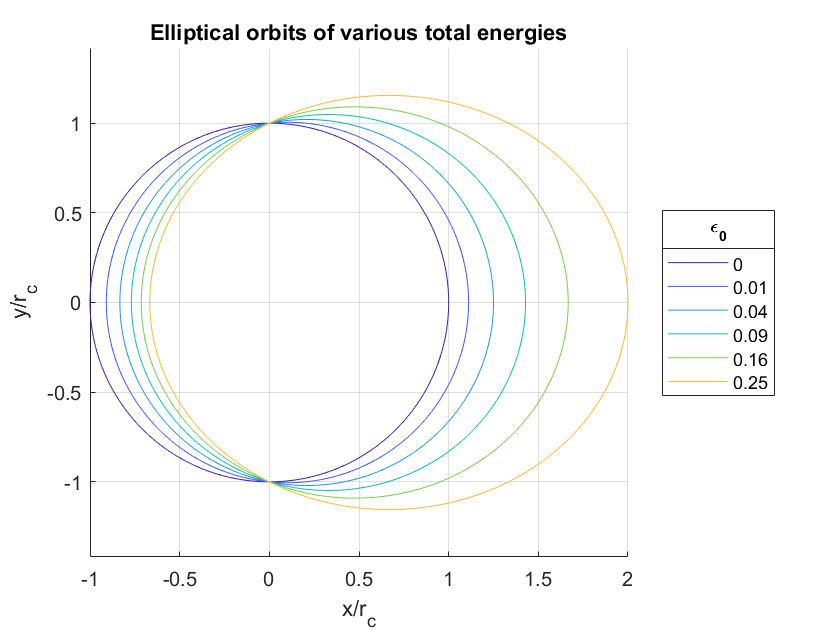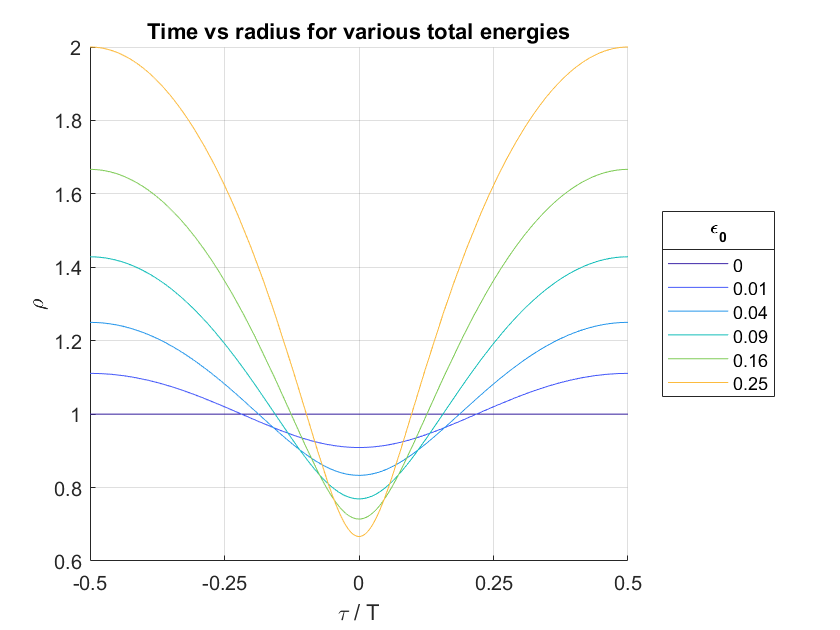

## Table of Contents

- Introduction

- Change of coordinates

- Conjugate momenta

- Hamilton's equations of motion

- The effective potential

- Finding radial extrema

- Weighing the earth

- Perturbations of circular orbits

- Solving the equations of motion

- Special case of initial conditions

- Geometric properties of elliptical orbits

- Solutions in terms of time

- Conclusion

## 1. Introduction

Consider two masses $M$ and $m$ in a coordinate frame with its origin at the center of $M$. The two masses interact through a gravitational potential of the form 

$V(|\mathbf{x}|) = - G M m \left| \mathbf{x} \right|^{-1}$,

where $\mathbf{x}$ is the vector position of $m$ relative to $M$, and $G$ is a physical constant. The Lagrangian is

$L = \frac{1}{2}m \left|\,\frac{d}{dt}\mathbf{x}\,\right|^2 + G M m |\mathbf{x}|^{-1}$.

## 2. Change of coordinates

Since the potential is a function of the distance between the masses, the Lagrangian can be simplified by converting to polar coordinates. Let's calculate the kinetic energy in polar coordinates using the `diff` function of Symbolic Math Toolbox.

Declare symbolic variables and functions with `syms`

syms r(t) theta(t)

Define the position vector `x` in terms of polar coordinates `r`, `theta.`

x = r * [cos(theta), sin(theta)];

Analytically differentiate `x` using `diff.`

Dx = diff(x);

Calculate the squared velocity by matrix-multiplying the row and column forms of `Dx`. In MATLAB, the `tranpose` or (.`')` operator calculates the transpose of a matrix, so `Dx'` is the transpose of `Dx`.

simplify(Dx * Dx.')

$$ans(t) = {r\left(t\right)}^{2}\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}+{\left(\frac{\partial }{\partial t}r\left(t\right)\right)}^{2}$$

The Lagrangian in polar coordinates is therefore

syms G M m

L = (1/2)*m*(diff(r)^2 + r^2 * diff(theta)^2) + G*M*m * r^-1

$$L(t) = \frac{m\,\left({r\left(t\right)}^{2}\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}+{\left(\frac{\partial }{\partial t}r\left(t\right)\right)}^{2}\right)}{2}+\frac{G\,M\,m}{r\left(t\right)}$$

## 3. Conjugate momenta

The Langrangian can be rewritten in terms of the conjugate momenta in preparation for deriving the Hamiltonian. We'll find the relation between the velocities and momenta; then we'll use these relations to substitute velocities for momenta in the Lagrangian.

The momenta $p_r, \,\, p_\theta$ conjugate to the positions $r, \,\, \theta$ are

$p_r = \frac{\partial L}{\partial \dot{r}}$,

$p_\theta = \frac{\partial L}{\partial \dot{\theta}}$ .

Since $\dot{r}$, $\dot{\theta}$ are themselves functions of time, the right hand sides of these relations are functional derivatives, which we can calculate with `functionalDerivative` of Symbolic Math Toolbox. 

To take these functional derivatives, we must treat $\dot{r}$, $\dot{\theta}$ as independent functions of time.

syms Dr(t) Dtheta(t)

Let's substitute the symbolic derivatives `diff(r), diff(theta)` with these functions in `L` using `subs` of Symbolic Math Toolbox.

L = subs(L, [diff(r), diff(theta)], [Dr, Dtheta]);

Now we can calculate the `functionalDerivative` of $L$ with respect to $\dot{r}(t)$, $\dot{\theta}(t)$.

syms p_r(t) p_theta(t)
eq(1) = p_r     == functionalDerivative(L, Dr);
eq(2) = p_theta == functionalDerivative(L, Dtheta);
eq(:)

$$ans = \left(\begin{array}{c} p_{r}\left(t\right)=m\,\mathrm{Dr}\left(t\right)\\ p_{\theta }\left(t\right)=m\,\mathrm{Dtheta}\left(t\right)\,{r\left(t\right)}^{2} \end{array}\right)$$

Rearrange these relations to solve for the velocities in terms of the momenta using `isolate` of Symbolic Math Toolbox.

eq(1) = isolate(eq(1), Dr);
eq(2) = isolate(eq(2), Dtheta);
eq(:)

$$ans = \left(\begin{array}{c} \mathrm{Dr}\left(t\right)=\frac{p_{r}\left(t\right)}{m}\\ \mathrm{Dtheta}\left(t\right)=\frac{p_{\theta }\left(t\right)}{m\,{r\left(t\right)}^{2}} \end{array}\right)$$

Use `subs` to substitute the `rhs` (right hand side) of these expressions in `L`,

Dr_of_p_r         = rhs(eq(1));
Dtheta_of_p_theta = rhs(eq(2));
L = subs(L, [Dr, Dtheta], [Dr_of_p_r, Dtheta_of_p_theta])

$$L(t) = \frac{m\,\left(\frac{{p_{r}\left(t\right)}^{2}}{m^{2}}+\frac{{p_{\theta }\left(t\right)}^{2}}{m^{2}\,{r\left(t\right)}^{2}}\right)}{2}+\frac{G\,M\,m}{r\left(t\right)}$$

Use `expand` to make the expression more aesthetically pleasing,

L = expand(L)

$$L(t) = \frac{{p_{r}\left(t\right)}^{2}}{2\,m}+\frac{{p_{\theta }\left(t\right)}^{2}}{2\,m\,{r\left(t\right)}^{2}}+\frac{G\,M\,m}{r\left(t\right)}$$

## 4. Hamilton's equations of motion

The Hamiltonian is derived from the Lagrangian in general by

$H = \sum_i p_i \dot{x}_i - L$,

where $p_i$ is the momentum conjugate to the generalized coordinate $x_i$. So, in our case the Hamiltonian is

$H = p_r\frac{dr}{dt} + p_\theta\frac{d\theta}{dt} - L$.

We calculate this symbolically as

H = p_r * Dr_of_p_r + p_theta * Dtheta_of_p_theta - L

$$H(t) = \frac{{p_{r}\left(t\right)}^{2}}{2\,m}+\frac{{p_{\theta }\left(t\right)}^{2}}{2\,m\,{r\left(t\right)}^{2}}-\frac{G\,M\,m}{r\left(t\right)}$$

Hamilton's equations of motion are, in general

$\dot{x}_i = \frac{\partial H}{\partial p_i}$,

$\dot{p}_i = - \frac{\partial H}{\partial x_i}$,

which we calculate analytically as

eq(1) = diff(r,t)       ==  functionalDerivative(H, p_r);
eq(2) = diff(p_r,t)     == -functionalDerivative(H, r);
eq(3) = diff(theta,t)   ==  functionalDerivative(H, p_theta);
eq(4) = diff(p_theta,t) == -functionalDerivative(H, theta);

eq(:)

$$ans = \left(\begin{array}{c} \frac{\partial }{\partial t}r\left(t\right)=\frac{p_{r}\left(t\right)}{m}\\ \frac{\partial }{\partial t}p_{r}\left(t\right)=\frac{{p_{\theta }\left(t\right)}^{2}-G\,M\,m^{2}\,r\left(t\right)}{m\,{r\left(t\right)}^{3}}\\ \frac{\partial }{\partial t}\theta \left(t\right)=\frac{p_{\theta }\left(t\right)}{m\,{r\left(t\right)}^{2}}\\ \frac{\partial }{\partial t}p_{\theta }\left(t\right)=0 \end{array}\right)$$

We see that the angular momentum is a constant of motion, or in other words: it is a conserved quantity.

## 5. The effective potential

Since the angular momentum is a constant of motion, we can reinterpret the Lagrangian as being made up of an effective potential $\phi$,

$L = \frac{p_r^2}{2 m} -\phi(r)$, 

where

syms r phi(r) p_theta G M m
phi(r) = p_theta^2 / (2 * m * r^2) - G*M*m / r

$$phi(r) = \frac{{p_{\theta }}^{2}}{2\,m\,r^{2}}-\frac{G\,M\,m}{r}$$

Let's analyze $\phi$ by finding its extrema. Call the value of $r$ at the extrema $r_c$. We can find the value of $r_c$ by using `solve` of Symbolic Math Toolbox.

syms r_c
eq = r_c == solve(diff(phi) == 0, r)

$$eq = r_{c}=\frac{{p_{\theta }}^{2}}{G\,M\,m^{2}}$$

To simplify further analysis, rewrite $\phi$ in terms of a dimensionless radius 

$\rho \equiv r / r_c$. 

We first rewrite $p_\theta$ in terms of $r_c$, 

eq = isolate(eq, p_theta);
phi(r) = subs(phi(r), p_theta, rhs(eq));

then rewrite $r$ in terms of $r_c \, \rho$.

syms rho
phi(rho) = subs(phi(r), r, r_c * rho);
phi = simplify(phi)

$$phi(rho) = -\frac{G\,M\,m\,\left(2\,\rho -1\right)}{2\,r_{c}\,\rho^{2}}$$

Rewriting this expression for analytical clarity, the effective potential as a function of $\rho$ is thus

$\phi(\rho) = - \frac{G M m}{2r_c}\left(2-\rho^{-1}\right)\rho^{-1} $,

which has a minimum value

$\min \phi(\rho) = \phi(1) = -\frac{GMm}{2r_c}$.

We can create a non-dimensional plot of the effective potential $\phi$ using `fplot` of Symbolic Math Toolbox by factoring out a unit of $GMm/2r_c$, which is equal to $-\phi(1)$.

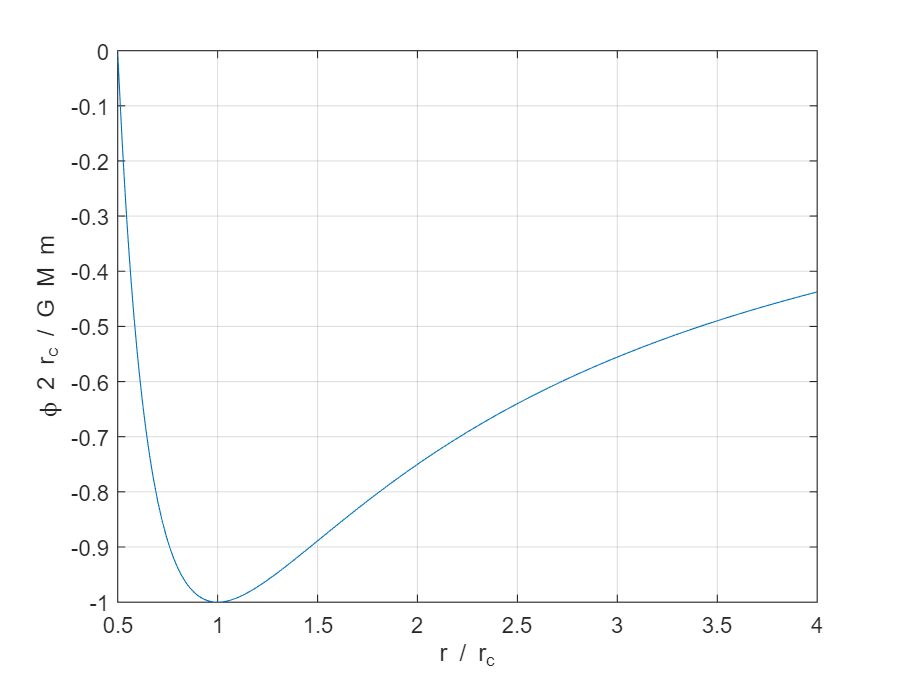

fplot(-phi / phi(1), [1/2, 4])

xlabel 'r / r_{c}';
ylabel '\phi 2 r_{c} / G M m';
grid on;

The shape of the effective potential indicates that there are three types of orbits:

- circular orbits of radius $r_c$ when the system is at its lowest energy state,

- bounded orbits with non-dimensional energy in the interval $(-1, 0]$ and radial positions bounded by the effective potential curve (sitting within the potential "well"), and

- unbounded "orbits" with energy $\geq$ 0.

## 6. Finding radial extrema

We can calculate the extreme radial positions of bounded orbits of particular energies with high numical precision using the `vpasolve` function of Symbolic Math Toolbox. VPA stands for Variable Precision Arithmetic.

Let's choose some non-dimensional energy for a bounded orbit, say -0.9.

energy = -0.9;

Set the numerical precision to, say, 50 digits and store the default precision.

digitsOld = digits(50);

Use `vpasolve` to find the non-dimensional radii `rho` such that `-phi(rho)/phi(1) == energy,`

rho_extreme = vpasolve(-phi(rho)/phi(1) == energy, rho)

$$rho\_extreme = \left(\begin{array}{c} 0.75974692664795785200012293950747571847560498451942\\ 1.4624752955742643702220992827147465037466172377028 \end{array}\right)$$

Restore the default precision,

digits(digitsOld);

## 7. Weighing the earth

Another interesting thing we can note from the chart of the effective potential is the required angular velocity $\omega_c$ to maintain a circular orbit. In the case of a circular orbit, the equation of motion for $\theta$ becomes

$\dot{\theta} = \frac{1}{m} p_\theta r_c^{-2} \equiv \omega_c$.

We can use the relation between $r_c$ and $p_\theta$ to find that

syms r_c G M m omega_c
p_theta = m * sqrt( G * M * r_c);
eq = omega_c^2 == ((1/m) * p_theta * r_c^-2)^2

$$eq = {\omega_{c}}^{2}=\frac{G\,M}{{r_{c}}^{3}}$$

Note that the required angular velocity does not depend on the mass of the orbiting object $m$.

The expression for the angular velocity of a circular orbit can be used to weigh the earth with the results of three experiments performed on earth to measure:

- the distance between the earth and the moon,

- the physical constant $G$, and

- the period of the moon's orbit around the earth.

Since this calculation involves units of measurement, let's keep track of units with `symunit` of Symbolic Math Toolbox.

u = symunit;

The `symunit` object `u` gives us access to a long list of units of measurement, such as meters, accessed with the syntax `u.m`. 

Let's use the `symunit` object `u` to set up the experimentally measured values we need to weigh the earth.

Two telescopes at different places on earth can give us the two angles we need to triangulate the distance to moon, which is about 

r_m = 3.8e8 * u.m

$$r\_m = 380000000\,m$$

The relative precision of a measurement is related to the number of significant digits by

$\textrm{Relative Precision} = \frac{1}{2} \times 10 \^ (-\,\textrm{Significant Digits})$,

so the relative precision of this measurement of the distance to the moon is

rp_r = 0.5 * 10^-2;

In 1798, Cavendish was the first to measure the coefficient $G$ with appreciable precision, although he expressed his results in terms of the density of the earth rather than $G$. His experiment was precise enough to report $G$ as

G_m  = 6.670e-11  * u.N * u.m^2 / u.kg^2;
rp_G = 0.5 * 10^-4; % relative precision

The period of the moon's orbit can be easily observed to be about 27 days

T_m  = 27 * u.d;
rp_T = 0.5 * 10^-2; % relative precision

We use `rewrite` to rewrite `T_m` in terms of seconds,

T_m = rewrite(T_m, u.s)

$$T\_m = 2332800\,s$$

The angular velocity is

omega_m  = 2*pi / T_m

$$omega\_m = \frac{\pi }{1166400}\,\frac{1}{s}$$

The relative precision of `omega_m` is related to that of `T_m` by

$\frac{d\omega_m}{\omega_m} = \frac{d(2\pi T_m^{-1})}{2\pi T_m^{-1}} = -\frac{dT_m}{T_m}$,

rp_omega = -rp_T; % relative precision

The mass of the earth is therefore

M_e = omega_m^2 * r_m^3 / G_m;
M_e = simplify(M_e); % simplify units

with a relative precision of

rp_M = 2*rp_omega + 3*rp_r - rp_G;

The number of significant digits of our calculation is

sd = -log10(2 * rp_M);

The mass of the earth is therefore calculated to be

M_e = vpa(M_e, sd)

$$M\_e = 6.0e+24\,\mathrm{kg}$$

This value at this precision is in agreement with the value given in reference materials such as [http://nssdc.gsfc.nasa.gov/planetary/factsheet/earthfact.html,](http://nssdc.gsfc.nasa.gov/planetary/factsheet/earthfact.html,) which states that

$M_{\textrm{e}} = 5.9723 \times 10^{24} \, \textrm{kg}$.

## 8. Perturbations of circular orbits

We can also use the effective potential to determine the frequency of radial oscilations of orbits that are slightly perturbed away from a circular orbit. Let's calculate the change in the potential away from a circular orbit up to second order in $d\rho$. We make use of the `taylor` function of Symbolic Math Toolbox to find that

% TAYLOR expand about rho = 1, truncate at order 3 (retain up to order 2)
deltaPhi = taylor(phi, rho, 1, 'order', 3) - phi(1)

$$deltaPhi(rho) = \frac{G\,M\,m\,{\left(\rho -1\right)}^{2}}{2\,r_{c}}$$

In terms of $r$, this is

$\left.\delta \phi\right|_{r=r_c} = \frac{1}{2}mGMr_c^{-3}(r-r_c)^2$.

This has the form of the standard harmonic oscillator potential with natural frequency $\omega_0$,

$V_{\textrm{harmonic}} = \frac{1}{2}m\omega_0^2\,x^2$,

so we can read off

$\omega_0^2 = GMr_c^{-3}$,

which is exactly the angular frequency of a circular orbit $\omega_c$,

$\omega_0 = \omega_c$.

## 9. Solving the equations of motion

We've deduced a lot from the equations of motion in the special case of circular orbits and in the general case without even solving them. Now let's work to solve them in the general case. To make further analysis simpler, let's rewrite the Hamiltonian in non-dimensional form. So far, we have

$H = \frac{p_r^2}{2m} - \frac{GMm}{2r_c}(2-\rho^{-1})\rho^{-1}$,

which can be rewritten as

$\epsilon = \pi_r^2 - (2-\rho^{-1})\rho^{-1}$,

where we've defined the non-dimensional Hamiltonian (the total energy) as

$\epsilon \equiv \frac{2 r_c}{GMm}H$,

and the non-dimensional momentum conjugate to $\rho$ as

$\pi_\rho \equiv \frac{r_c}{p_\theta} p_r$.

The equations of motion become

$\frac{d\rho}{dt} = \frac{p_\theta}{m}r_c^{-2}\pi_\rho$,

$\frac{d\pi_\rho}{dt} = \frac{p_\theta}{m} r_c^{-2}(\rho^{-1}-1)\rho^{-2}$,

$\frac{d\theta}{dt} = \frac{p_\theta}{m}r_c^{-2}\rho^{-2}$,

$\frac{dp_\theta}{dt}= 0$.

We can additionally define the non-dimensional time $\tau$ as

$\tau \equiv \frac{p_\theta}{m r_c^2} t$,

so the equations of motion become fully non-dimensional,

$\frac{d\rho}{d\tau} = \pi_\rho$,

$\frac{d\pi_\rho}{d\tau} =(\rho^{-1}-1)\rho^{-2}$,

$\frac{d\theta}{d\tau} =\rho^{-2}$,

$\frac{dp_\theta}{d\tau}= 0$.

Since the momentum $p_\theta$ is a constant of motion, we can rewrite the equations of motion by making a change of variables from time to polar angle. This change of variables is defined by the equation of motion for $\theta$.

We make the change of variables as follows

syms rho(theta) pi_rho(theta)

% equations of motion
DrhoDtau    = pi_rho;
Dpi_rhoDtau = (rho^-1 - 1)*rho^-2;
DthetaDtau  = rho^-2;

% change of variables
eq(1) = diff(rho,theta)    == DrhoDtau    / DthetaDtau;
eq(2) = diff(pi_rho,theta) == Dpi_rhoDtau / DthetaDtau;
eq(:)

$$ans = \left(\begin{array}{c} \frac{\partial }{\partial \theta }\rho \left(\theta \right)=\pi_{\rho }\left(\theta \right)\,{\rho \left(\theta \right)}^{2}\\ \frac{\partial }{\partial \theta }\pi_{\rho }\left(\theta \right)=\frac{1}{\rho \left(\theta \right)}-1 \end{array}\right)$$

The equations of motion form a system of nonlinear ODEs. The system can be linearized by the substitution $u = \rho^{-1}$ since

syms u(theta)
eq = subs(eq, rho, 1/u);
eq(:)

$$ans = \left(\begin{array}{c} -\frac{\frac{\partial }{\partial \theta }u\left(\theta \right)}{{u\left(\theta \right)}^{2}}=\frac{\pi_{\rho }\left(\theta \right)}{{u\left(\theta \right)}^{2}}\\ \frac{\partial }{\partial \theta }\pi_{\rho }\left(\theta \right)=u\left(\theta \right)-1 \end{array}\right)$$

Multiply the first equation by $-u^2$ and the system becomes

eq(1) = - u^2 * eq(1);
eq(:)

$$ans = \left(\begin{array}{c} \frac{\partial }{\partial \theta }u\left(\theta \right)=-\pi_{\rho }\left(\theta \right)\\ \frac{\partial }{\partial \theta }\pi_{\rho }\left(\theta \right)=u\left(\theta \right)-1 \end{array}\right)$$

The linearized system of ODEs can be solved analytically using `dsolve` of Symbolic Math Toolbox.

syms u(theta) rho(theta) pi_rho(theta) rho_0 pi_rho_0

% set up system of ODEs
ode = [diff(u,theta)      == - pi_rho;
       diff(pi_rho,theta) == u - 1];

% set up initial conditions
cond = [ u(0) == 1 / rho_0;
    pi_rho(0) == pi_rho_0];

s = dsolve(ode, cond);

eq(1) =    rho(theta) == 1 / s.u;
eq(2) = pi_rho(theta) == s.pi_rho;
eq(:)

$$ans = \left(\begin{array}{c} \rho \left(\theta \right)=\frac{1}{\cos\left(\theta \right)\,\left(\cos\left(\theta \right)+\frac{1}{\rho_{0}}-1\right)-\sin\left(\theta \right)\,\left(\pi_{\rho ,0}-\sin\left(\theta \right)\right)}\\ \pi_{\rho }\left(\theta \right)=\cos\left(\theta \right)\,\left(\pi_{\rho ,0}-\sin\left(\theta \right)\right)+\sin\left(\theta \right)\,\left(\cos\left(\theta \right)+\frac{1}{\rho_{0}}-1\right) \end{array}\right)$$

The solutions can be rewritten as

$\rho(\theta) = \left[(\rho_0^{-1} - 1)\cos\theta +1 - \pi_{\rho,0}\sin\theta\right]^{-1}$,

$\pi_\rho(\theta) = (\rho_0^{-1} - 1)\sin\theta + \pi_{\rho,0}\cos\theta$.

The inital values are constrained by the total energy $\epsilon$,

$\epsilon = \pi_{\rho,0}^2 - \rho_0^{-1}(2-\rho_0^{-1})$,

or

$\pi_{\rho,0} = \pm\left[\epsilon + \rho_0^{-1}(2 - \rho_0^{-1})\right]^{1/2}$.

## 10. Special case of initial conditions

Let's choose initial conditions that correspond to the situation where $\rho$ is at one of its extrema (either minimum or maximum). In this case, the equation of motion for $\rho$ is

$\left.\frac{d\rho}{d\theta}\right|_0 = 0 = \pi_{\rho,0}\,\rho_0^{-2}$,

which, for finite $\rho_0$ (or closed orbits), requires

$\pi_{\rho,0} = 0$.

The energy is then

$\epsilon = - \rho_0^{-1}(2-\rho_0^{-1})$.

Let's recast this equation to solve for $\rho_0$ in terms of $\epsilon$.

syms epsilon rho_0;
sol_rho_0 = solve(epsilon == -(1/rho_0)*(2 - 1/rho_0),rho_0)

$$sol\_rho\_0 = \left(\begin{array}{c} -\frac{1}{\sqrt{\epsilon +1}-1}\\ \frac{1}{\sqrt{\epsilon +1}+1} \end{array}\right)$$

Let's choose the minimum value between these two solutions. To figure out which is smaller, determine whether their difference is less or greater than zero. Recall from the discussion of the effective potential that for elliptical orbits $-1 < \epsilon < 0$. We can impose these conditions on $\epsilon$ using the `assume` and `assumeAlso` functions of Symbolic Math Toolbox.

assume(epsilon < 0);
assumeAlso(epsilon > -1);
sign(sol_rho_0(2) - sol_rho_0(1))

$$ans = -1$$

which implies

`sol_rho_0(2) < sol_rho_0(1).`

We could also check this assertion with `isAlways` of Symbolic Math Toolbox,

isAlways(sol_rho_0(2) < sol_rho_0(1))

ans = logical
   1


So, we choose the initial value to be equal to `sol_rho_0(2)`,

eq = rho_0 == sol_rho_0(2)

$$eq = \rho_{0}=\frac{1}{\sqrt{\epsilon +1}+1}$$

With these initial conditions, the solutions to the equations of motion become

$\rho(\theta) = \left(1 + \sqrt{\epsilon+1}\cos\theta\right)^{-1}$,

$\pi_\rho(\theta) = \sqrt{\epsilon + 1}\sin\theta$.

Recall from the plot of the effective potential energy that the lowest energy for a closed orbit is that of a circular orbit, with an energy $\epsilon_c = -1$. Let's define the shifted energy $\epsilon_0$ as

$\epsilon_0 \equiv \epsilon - \epsilon_c = \epsilon + 1$,

so the lowest value of the shifted energy is zero. In terms of the shifted energy, the solutions to the equations of motion become

$\rho(\theta) = \left(1 + \sqrt{\epsilon_0}\cos\theta\right)^{-1}$,

$\pi_\rho(\theta) = \sqrt{\epsilon_0}\sin\theta$.

## 11. Geometric properties of elliptical orbits

The solution for $\rho(\theta)$ can be compared with the general equation of an ellipse with eccentricity $e$ and major axis $a$,

$R(\theta) = a(1-e^2) (1 + e\cos\theta)^{-1}$,

thus the eccentricity of an elliptical orbit is related to the shifted energy by

syms epsilon_0
e = sqrt(epsilon_0)

$$e = \sqrt{\epsilon_{0}}$$

The major axis $a$ of the orbit is

a = 1/(1-e^2)

$$a = -\frac{1}{\epsilon_{0}-1}$$

The minor axis $b$ is related to $a$ and $e$ by

b = a * sqrt(1 - e^2);

and in terms of $\epsilon_0$,

display(b);

$$b = \frac{1}{\sqrt{1-\epsilon_{0}}}$$

The distance from the center of the ellipse to either focus $f$ is related to $a$ and $b$ by

f = sqrt(a^2 - b^2);

and in terms of $\epsilon_0$,

f = simplify(f)

$$f = \sqrt{\frac{\epsilon_{0}}{{\left(\epsilon_{0}-1\right)}^{2}}}$$

We can plot elliptical orbits for different choices of the shifted energy $\epsilon_0$ using the implicit equation of an ellipse and the plotting function `fimplicit` of Symbolic Math Toolbox

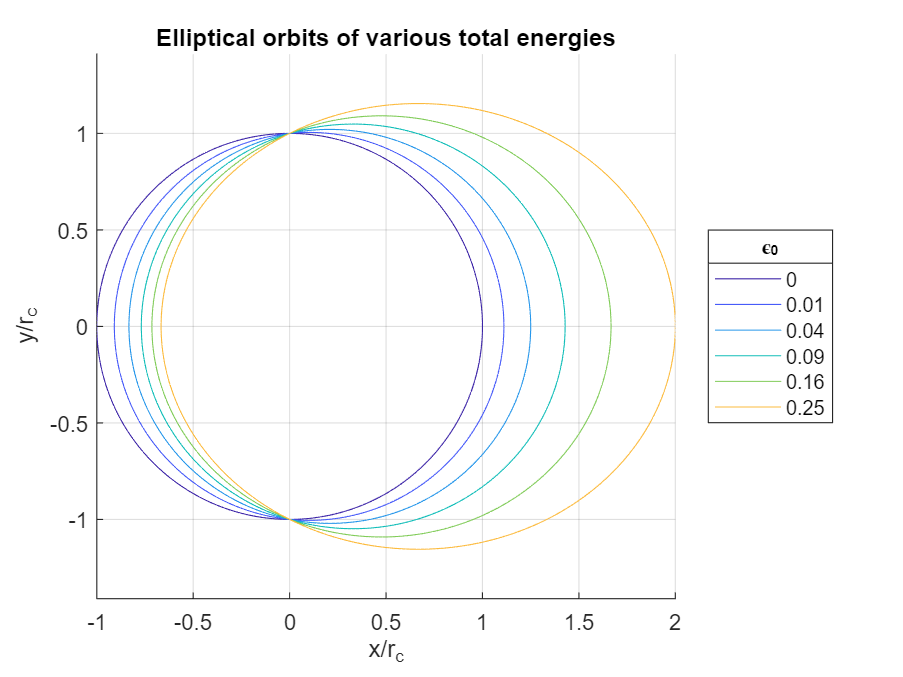

syms x y

% range of epsilon_0
e = (0 : 0.1 : 0.5).^2;

figure;

% matrix of RGB values to color each orbit
color = colormap(parula(length(e)+1));

hold on;
for k = 1:length(e)
    a = 1/(1-e(k));
    b = 1/sqrt(1-e(k));
    f = sqrt(e(k))/(1-e(k));
    fimplicit(((x-f)/a)^2 + (y/b)^2 == 1, 'Color', color(k,:));
end
hold off;

xlabel('x/r_c');
ylabel('y/r_c');
title('Elliptical orbits of various total energies');
lgd = legend(split(num2str(e)));
lgd.Location = 'eastoutside';
lgd.Title.String = '\epsilon_0';
axis equal;
grid on;

## 12. Solution in terms of time

So far, we've derived expressions for the radial position and momentum in terms of the polar angle $\theta$. We can derive their dependence on time by making use of the equation of motion for $\theta$, which we recall is

$\frac{d\theta}{d\tau} =\rho^{-2}
$,

or

$\frac{d\tau}{d\theta} = \rho^{2}(\theta)$.

or more explicitly,

$\frac{d\tau}{d\theta} = \left(1+\sqrt{\epsilon_0}\cos\theta\right)^{-2}$,

where $\tau$ is the non-dimensional time we defined earlier as

$\tau \equiv \frac{p_\theta}{m\,r_c^2} t$.

We can solve this differential equation for $\tau$ by using `dsolve`,

syms rho(theta) tau(theta) epsilon_0
rho(theta) = 1/(1+sqrt(epsilon_0)*cos(theta));
sol = dsolve(diff(tau,theta) == rho^2, tau(0) == 0);
tau(epsilon_0, theta) = simplify(sol)

$$tau(epsilon\_0, theta) = \frac{\sqrt{\epsilon_{0}}\,\sin\left(\theta \right)}{\left(\sqrt{\epsilon_{0}}\,\cos\left(\theta \right)+1\right)\,\left(\epsilon_{0}-1\right)}-\frac{2\,\mathrm{atanh}\left(\frac{\tan\left(\frac{\theta }{2}\right)\,\sqrt{\epsilon_{0}-1}}{\sqrt{\epsilon_{0}}+1}\right)}{{\left(\epsilon_{0}-1\right)}^{3/2}}$$

Let's plot this function to explore its behavior.

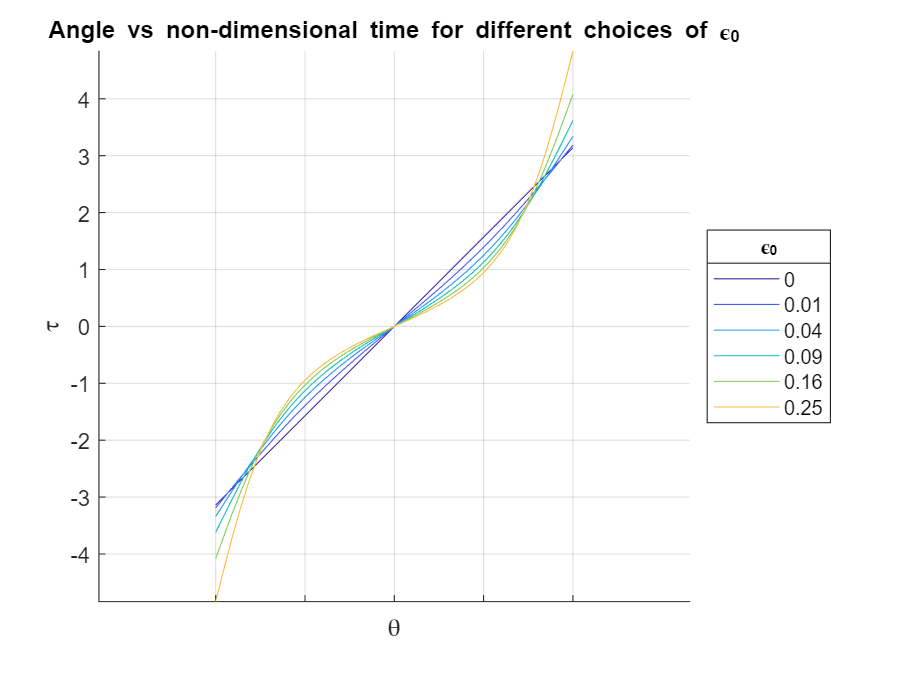

figure;

hold on;
for k = 1:length(e)
    fplot(tau(e(k), theta), [-pi pi], 'Color', color(k,:));
end
hold off;

thetaTicks = linspace(-pi, pi, 5);
xticks(thetaTicks);
% write labels in terms of pi
xticklabels(split(extractBetween(texlabel(sym(thetaTicks)),'[[',']]'),', '));

xlabel('\theta');
ylabel('\tau');
title('Angle vs non-dimensional time for different choices of \epsilon_0');
lgd = legend(split(num2str(e)));
lgd.Location = 'eastoutside';
lgd.Title.String = '\epsilon_0';
axis equal;
grid on;

This expression for $\tau(\theta)$ contains the term $\tan(\theta/2)$, which is only defined on the open interval $\theta \in (-\pi,\, \pi)$, or in other words, not at $\theta = \pm\pi$, which we can verify with `limit` of Symbolic Math Toolbox

limit(tan(theta/2), theta, pi)

$$ans = \mathrm{NaN}$$

This presents a problem if were to try to use this expression to calculate the non-dimensional oribtal period $T$, because

$T = 2 \, \tau(\pi)$.

However, we can evaluate $\tau$ at $\pi$ by calculating the definite integral over the closed interval $[0,\,\pi]$


$$\tau(\pi) = \int_0^\pi d\theta\,\,\rho^{2}(\epsilon_0,\theta)$$


using `int` of Symbolic Math Toolbox. This integral is guaranteed to converge by Lebesgue's theorem, which states

*    a bounded function on *$[a,\,b]$* is Riemann integrable if and only if it is continuous almost everywhere.*

Since we're analyzing bounded orbits, $\rho^2$ is surely bounded and continuous everywhere on $[0,\pi]$. 

Let's evaluate $T$ for the case of $\epsilon_0 = 1/4$ as an example.

rho(epsilon_0, theta) = 1/(1+sqrt(epsilon_0)*cos(theta));
T = 2 * int(rho(1/4, theta)^2, theta, 0, pi)

$$T = \frac{16\,\pi \,\sqrt{3}}{9}$$

Let's plot the radial position vs time using `fplot`.

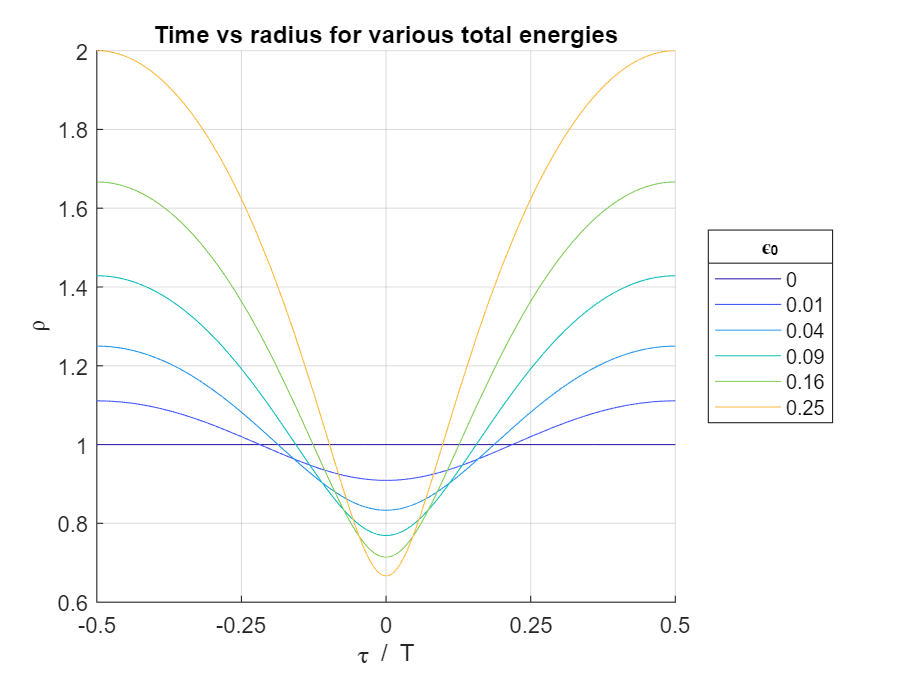

figure;

hold on;
for k = 1:length(e)
    T = 2 * int(rho(e(k), theta)^2, theta, 0, pi); % orbital period
    fplot(tau(e(k),theta) / T, rho(e(k),theta), [-pi pi], 'Color', color(k,:));
end
hold off;

xticks(-0.5 : 0.25 : 0.5);

xlabel('\tau / T');
ylabel('\rho');
title('Time vs radius for various total energies');
lgd = legend(split(num2str(e)));
lgd.Location = 'eastoutside';
lgd.Title.String = '\epsilon_0';
grid on;

We can also plot the radial momentum vs time in the same fashion.

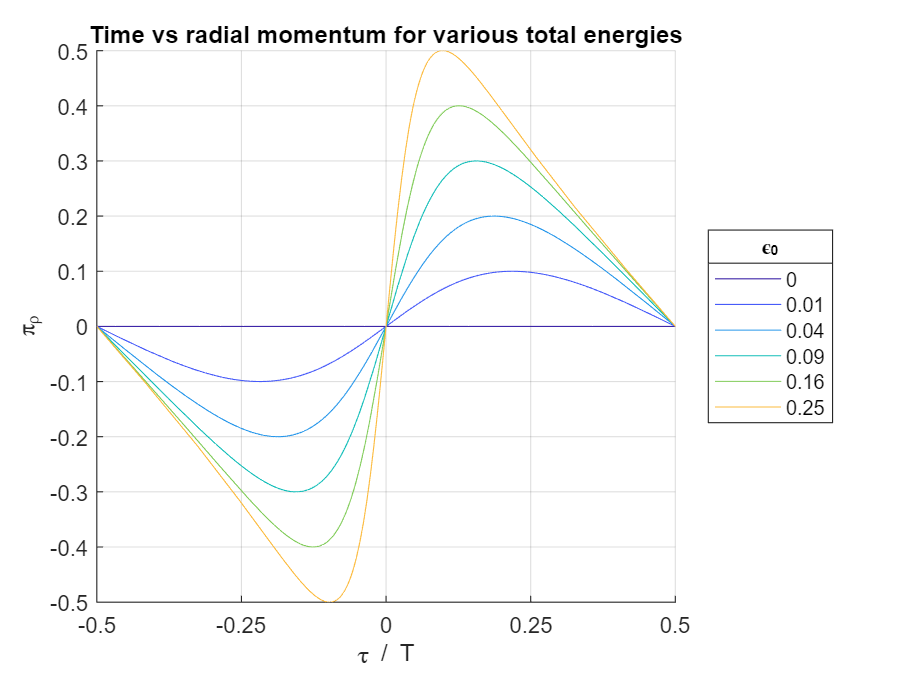

pi_rho(epsilon_0, theta) = sqrt(epsilon_0)*sin(theta);

figure;

hold on;
for k = 1:length(e)
    T = 2 * int(rho(e(k), theta)^2, theta, 0, pi); % orbital period
    fplot(tau(e(k),theta)/T, pi_rho(e(k),theta), [-pi pi], 'Color', color(k,:));
end
hold off;

xticks(-0.5 : 0.25 : 0.5);

xlabel('\tau / T');
ylabel('\pi_\rho');
title('Time vs radial momentum for various total energies');
lgd = legend(split(num2str(e)));
lgd.Location = 'eastoutside';
lgd.Title.String = '\epsilon_0';
grid on;

## 13. Conclusion

We've analytically explored various aspects of the Kepler problem by using many of the key features of Symbolic Math Toolbox, such as

- `syms` 

- `diff`

- `simplify `

- `subs `

- `functionalDerivative `

- `isolate `

- `rhs / lhs `

- `expand `

- `solve `

- `fplot `

- `digits `

- `vpasolve `

- `symunit `

- `rewrite`

- `vpa `

- `taylor `

- `dsolve `

- `assume `

- `isAlways `

- `fimplicit`

- `int`

© 2017 The MathWorks, Inc.